close all
clear
clc

syms x y t r z real
syms e n mu beta mu_0 epsilon_0 f real positive
syms pi

% Computed parameters
c_0=1/sqrt(epsilon_0*mu_0);
v=beta*c_0;
epsilon=n^2*epsilon_0;

syms c_0 v epsilon
assume(v,'positive')
assume(beta^2*n^2>1)

% Pick up frequency
omega=2*pi*f;

% Andrades' term
k_r=omega/v*sqrt(1-beta^2*n^2);

% Analytical solution in cylindrical coordinates (without limit of Bessel function)
% Ewr=+e*abs(omega)/(2*pi*epsilon*v^2)*...
%      sqrt(1-beta^2*n^2)*besselk(1,k_r*r).*...
%      exp(-1i*omega*z/v);
% Ewz=+e*abs(omega)/(2*pi*epsilon*v^2)*...
%      1i*(1-beta^2*n^2)*besselk(0,k_r*r).*...
%      exp(-1i*omega*z/v);
% Hwp=+e*abs(omega)/(2*pi*v)*...
%      sqrt(1-beta^2*n^2)*besselk(1,k_r*r).*...
%      exp(-1i*omega*z/v);

% Analytical solution in cylindrical coordinates (with limit of Bessel function)
Ewr=+e/(2*pi*epsilon*v)*...
     sqrt(1i*pi*abs(k_r)./(2*r)).*...
     exp(-1i*(abs(k_r)*r+omega*z/v));
Ewz= -e/(2*pi*epsilon*v)*...
     sqrt(1i*pi*abs(k_r)*(beta^2*n^2-1)./(2*r)).*...
     exp(-1i*(abs(k_r)*r+omega*z/v));
Hwp= +e/(2*pi)*...
     sqrt(1i*pi*abs(k_r)./(2*r)).*...
     exp(-1i*(abs(k_r)*r+omega*z/v));

% Impose analytical solution
Hw= subs(Hwp,[r,z],[abs(y),x]).*sign(y)

$$Hw = \frac{e\,\sqrt{f}\,{\mathrm{e}}^{-\frac{2\,\pi \,f\,x\,\mathrm{i}}{v}-\frac{2\,\pi \,f\,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{v}}\,\mathrm{sign}\left(y\right)\,\sqrt{\frac{\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\left|y\right|}}}{2\,\sqrt{v}}$$

Ew=[subs(Ewz,[r,z],[abs(y),x])
    subs(Ewr,[r,z],[abs(y),x]).*sign(y)]

$$Ew = \left[\begin{array}{c} -\frac{e\,\sqrt{f}\,{\mathrm{e}}^{-\frac{2\,\pi \,f\,x\,\mathrm{i}}{v}-\frac{2\,\pi \,f\,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{v}}\,\sqrt{\frac{{\left(\beta^{2}\,n^{2}-1\right)}^{3/2}\,\mathrm{i}}{\left|y\right|}}}{2\,\epsilon \,v^{3/2}}\\ \frac{e\,\sqrt{f}\,{\mathrm{e}}^{-\frac{2\,\pi \,f\,x\,\mathrm{i}}{v}-\frac{2\,\pi \,f\,\left|y\right|\,\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{v}}\,\mathrm{sign}\left(y\right)\,\sqrt{\frac{\sqrt{\beta^{2}\,n^{2}-1}\,\mathrm{i}}{\left|y\right|}}}{2\,\epsilon \,v^{3/2}} \end{array}\right]$$


% Put numerical values
f=2; beta=1; n=2; v=1; epsilon=n^2; e=1;

% Plot Ewx
Ewx=eval(Ew(1))

$$Ewx = -\frac{\sqrt{2}\,{\mathrm{e}}^{-4\,\pi \,x\,\mathrm{i}-4\,\pi \,\sqrt{3}\,\left|y\right|\,\mathrm{i}}\,\sqrt{\frac{3\,\sqrt{3}\,\mathrm{i}}{\left|y\right|}}}{8}$$

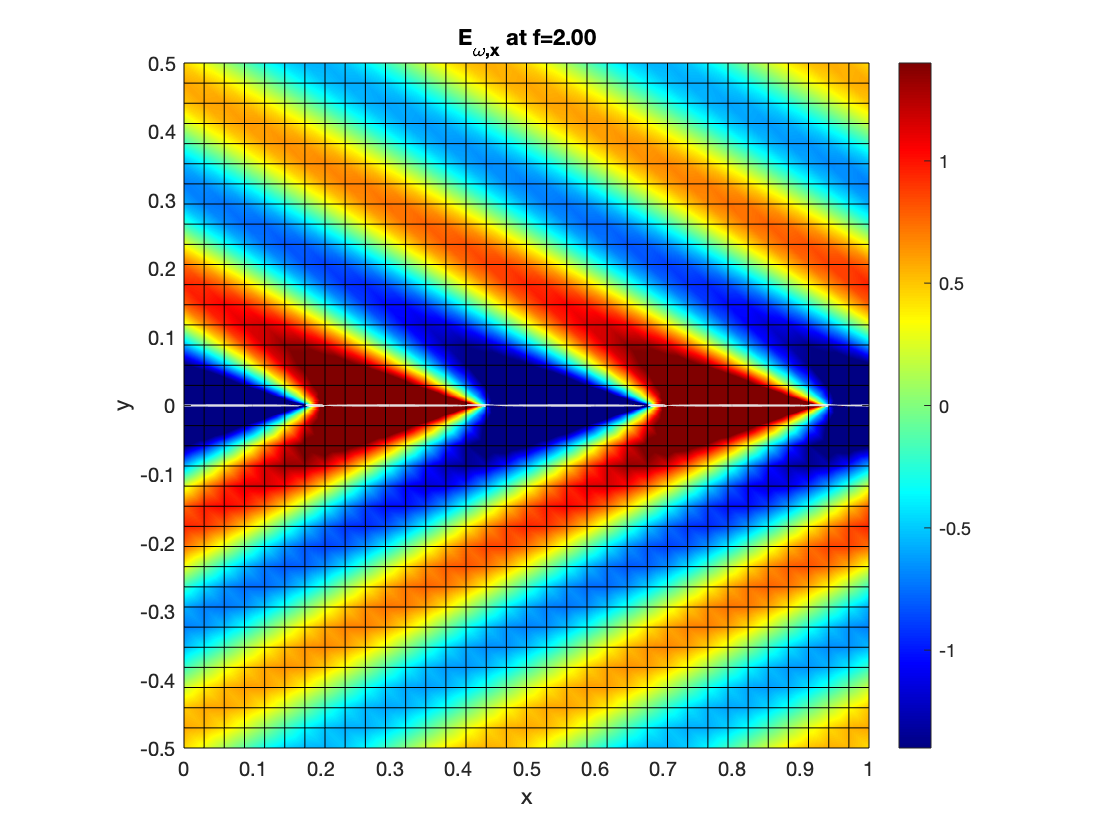

fsurf(real(Ewx),[0,1,-0.5,+0.5])
box on; axis equal; shading interp; colormap jet; colorbar; view(2);
title(sprintf('E_{\\omega,x} at f=%.2f',f)); xlabel('x'); ylabel('y');
caxis(caxis/50)


% Plot Ewy
Ewy=eval(Ew(2))

$$Ewy = \frac{\sqrt{2}\,{\mathrm{e}}^{-4\,\pi \,x\,\mathrm{i}-4\,\pi \,\sqrt{3}\,\left|y\right|\,\mathrm{i}}\,\mathrm{sign}\left(y\right)\,\sqrt{\frac{\sqrt{3}\,\mathrm{i}}{\left|y\right|}}}{8}$$

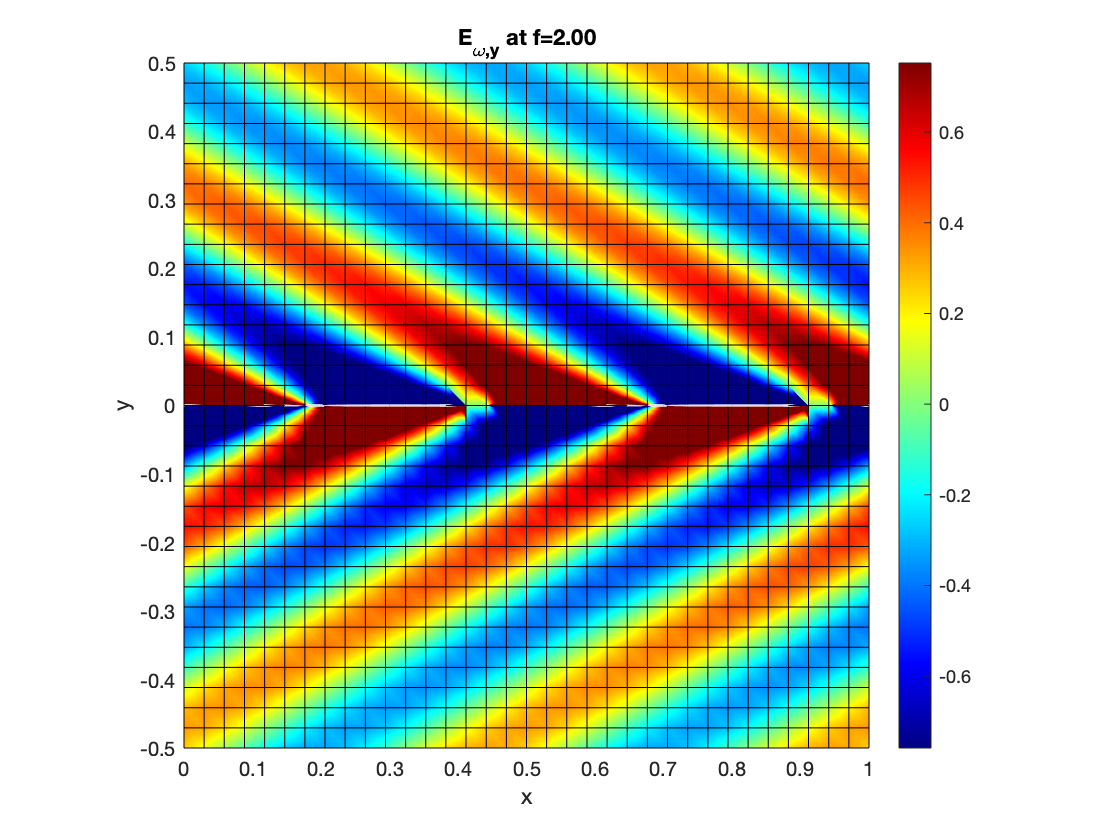

fsurf(real(Ewy),[0,1,-0.5,+0.5])
box on; axis equal; shading interp; colormap jet; colorbar; view(2);
title(sprintf('E_{\\omega,y} at f=%.2f',f)); xlabel('x'); ylabel('y');
caxis(caxis/50)


% Plot Hwz
Hwz=eval(Hw)

$$Hwz = \frac{\sqrt{2}\,{\mathrm{e}}^{-4\,\pi \,x\,\mathrm{i}-4\,\pi \,\sqrt{3}\,\left|y\right|\,\mathrm{i}}\,\mathrm{sign}\left(y\right)\,\sqrt{\frac{\sqrt{3}\,\mathrm{i}}{\left|y\right|}}}{2}$$

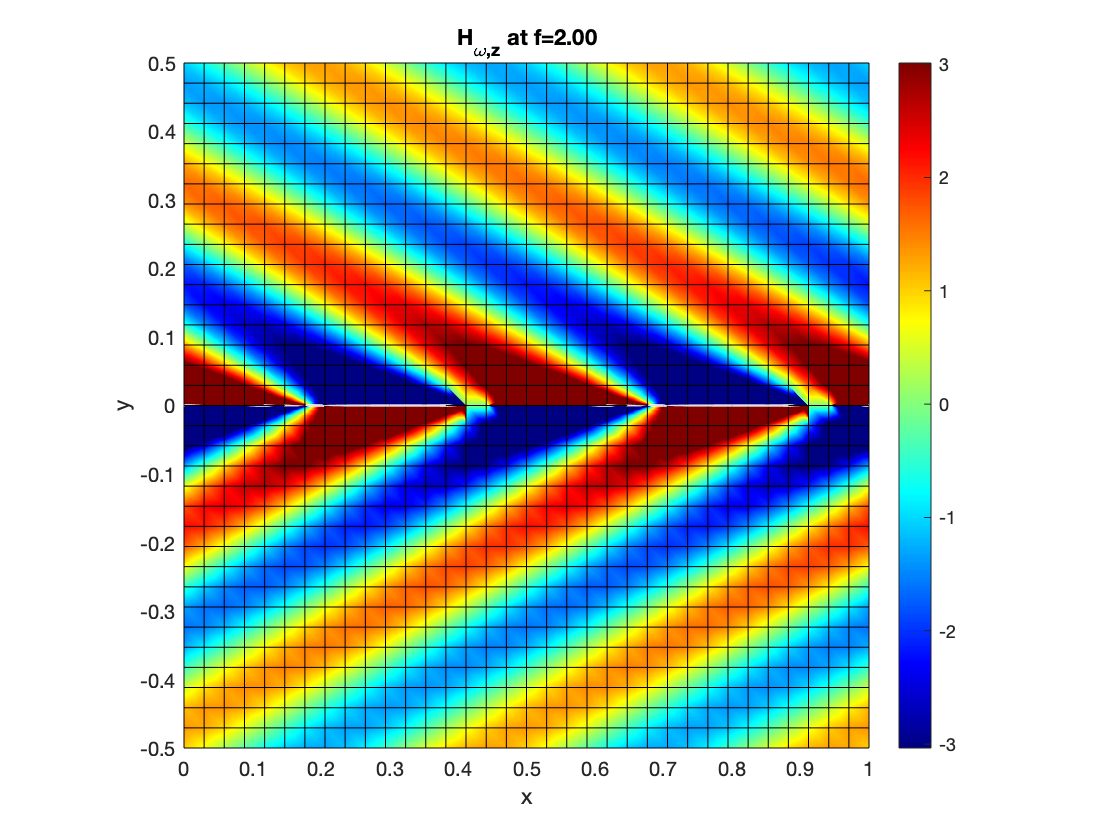

fsurf(real(Hwz),[0,1,-0.5,+0.5])
box on; axis equal; shading interp; colormap jet; colorbar; view(2);
title(sprintf('H_{\\omega,z} at f=%.2f',f)); xlabel('x'); ylabel('y');
caxis(caxis/50)